# Wiener filters

## Exam 2015 Problem 3: Recover signal by a Wiener filter

clear variables;

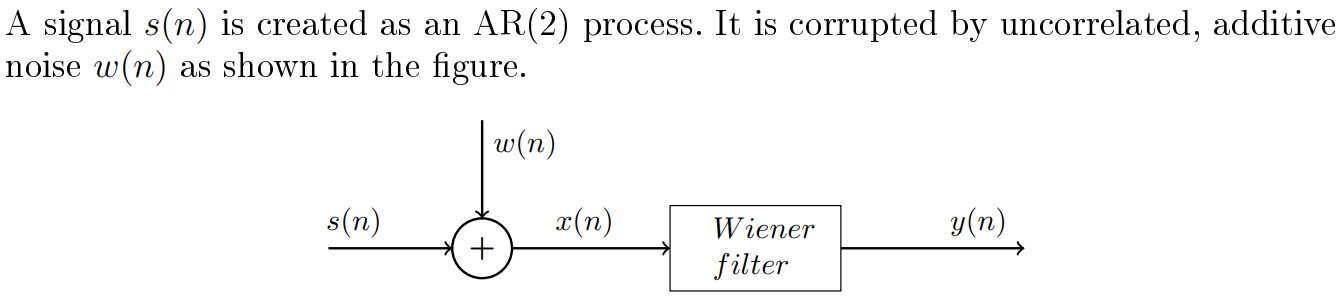

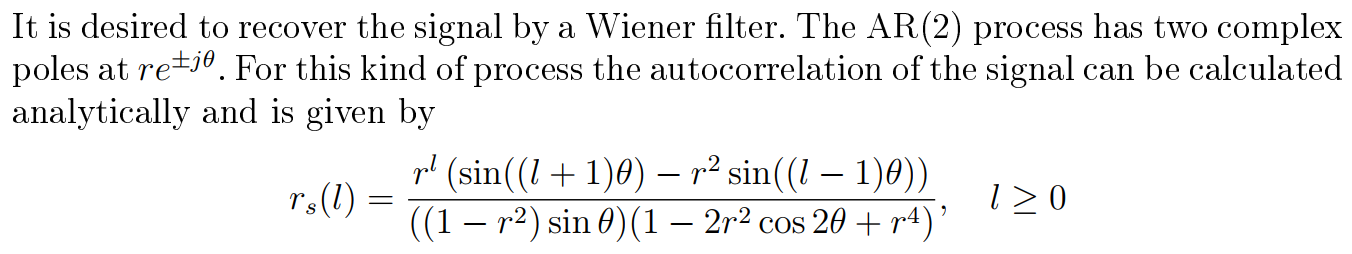

For simplicity the first few values of the autocorrelation function for this specific process is given by  

        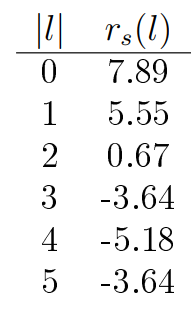

r_ss = [7.89, 5.55, 0.67, -3.64, -5.18, -3.64];

Less information is known about the noise. The autocorrelation for the first few lags are given by:

          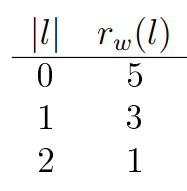

For all other lags, the autocorrelation, $r_w \left(l\right)$ is assumed to be zero.

r_ww = [5, 3, 1, 0, 0, 0];

### 1) Design a 4 tap Wiener filter to recover *s*(*n*).

The $p$-order Wiener filter for estimating the signal $s\left(n\right)$ is given by:

        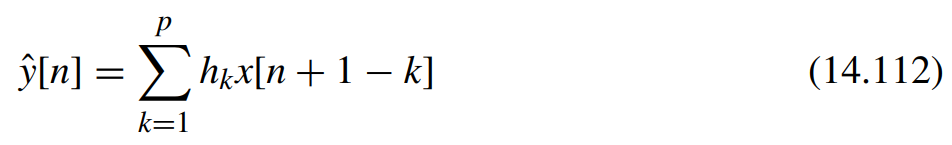

The optimum Wiener filter coefficients is given by the Wiener-Hopf equation:

        

where ${\mathit{\mathbf{R}}}_x$ is the autocorrelation matrix of the corrupted signal $s\left(n\right)$ and $\mathit{\mathbf{g}}$ is the cross-correlation between the desired signal $s\left(n\right)$ and the corrupted signal $x\left(n\right)$.

Designing a Wiener filter to recover a corrupted signal involves 3 steps:

- Compute the autocorrelation sequence $r_x \left(\ell \right)$ and matrix $R_x$

- Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$

- Solve the Wiener-Hopf equation to find the optimum Wiener filter coefficients

**Step 1: **Compute the autocorrelation $r_x \left(\ell \right)$:

Since the signal $s\left(n\right)$ and the noise $w\left(n\right)$ are uncorrelated the autocorrelation function of $s\left(n\right)$ is just the sum of the individual autocorrelation functions:

        
$$rx\left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(s\left(n\right)+w\left(n\right)\right)\left(s\left(n-\ell \right)+w\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)w\left(n-\ell \right)+w\left(n\right)s\left(n-\ell \right)+w\left(n\right)w\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+r_{\textrm{sw}} \left(\ell \right)+r_{\textrm{sw}} \left(\ell \right)+r_w \left(\ell \right)$$


                 $=r_s \left(\ell \right)+r_w \left(\ell \right)$ (assuming $s\left(n\right)$ and $w\left(n\right)$ are uncorrelated)

p = 4;
r_xx = r_ss + r_ww;
R_xx = toeplitz(r_xx(1:p))

R_xx =    12.8900    8.5500    1.6700   -3.6400
    8.5500   12.8900    8.5500    1.6700
    1.6700    8.5500   12.8900    8.5500
   -3.6400    1.6700    8.5500   12.8900


**Step 2:** Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$:

Since the desired signal is $s\left(n\right)$, the cross-correlation between $s\left(n\right)$ and $s\left(n\right)$ simplifies to the autocorrelation of the signal $r_s \left(\ell \right)$:

        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)\left(s\left(n-\ell \right)+w\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)w\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+r_{\mathrm{sw}} \left(\ell \right)$$


                 $=r_s \left(\ell \right)$   (assuming $s\left(n\right)$ and $w\left(n\right)$ are uncorrelated)

g = r_ss(1:p)'

g =     7.8900
    5.5500
    0.6700
   -3.6400


**Step 3:** Compute the optimum filter coefficients:

h_opt = R_xx\g

h_opt =     0.4841
    0.1026
    0.0477
   -0.1906


### 2) Calculate the minimum mean square error (MSE)

The minimum value of the mean square error $E\left\lbrack e^2 \left(n\right)\right\rbrack E\left\lbrack {\left(y\left(n\right)-\hat{y} \left(n\right)\right)}^2 \right\rbrack$ is given by  

        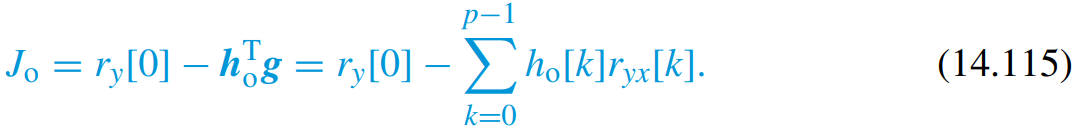

mse = r_ss(1) - h_opt'*g

mse = 2.7757

### 3) Can the MSE be lowered using a longer Wiener filter?

*Explain whether the minimum mean square error can be lowered by using a longer Wiener filter when we only have sparse knowledge of the noise. *

The minimum mean square error can be reduced further by increasing the length of the Wiener filter. As the length of the fiter is increased the frequency resolution increases and the spectral shape of the filter becomes better suited for passing the signal and rejecting the noise. 

This is also evident if the minimum mean square error is calculated. For a 5 tap filter, the minimum mean square error decreases to 2.6617:

p = 5;
r_xx = r_ss + r_ww;
R_xx = toeplitz(r_xx(1:p));
g = r_ss(1:p)';
h_opt = R_xx\g;
mse = r_ss(1) - h_opt'*g

mse = 2.6617

### 4) Calculate SNR before and after the Wiener filter

The signal to noise ratio of the input signal is given by

        
$${\textrm{SNR}}_i =\frac{\mathrm{power}\;\mathrm{of}\;\mathrm{signal}}{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{r_s \left(0\right)}{r_w \left(0\right)}$$


SNR_i = r_ss(1) / r_ww(1)

SNR_i = 1.5780

The output SNR of the Wiener filter is given by:

        
$${\textrm{SNR}}_o =\frac{h_{\textrm{opt}}^T R_s h_{\textrm{opt}} }{h_{\textrm{opt}}^T R_w h_{\textrm{opt}} }$$


R_ss = toeplitz(r_ss(1:p));
R_ww = toeplitz(r_ww(1:p));
SNR_o = (h_opt'*R_ss*h_opt) / (h_opt'*R_ww*h_opt)

SNR_o = 2.2673

The filter increases the signal to noise ratio but only slightly. This is expected and is an excellent way to check your results.

## Exam 2017 Problem 4: Recover signal using a Wiener filter

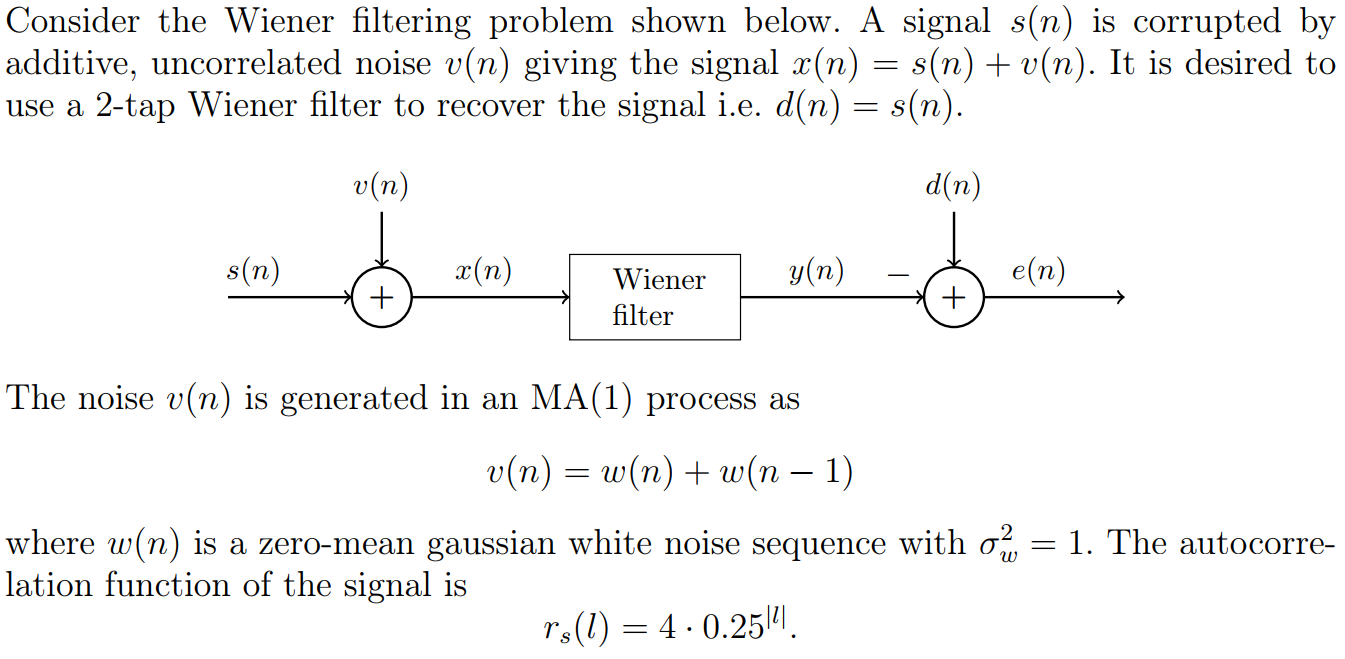

clear variables;

M = 2;
ell = 0:M-1;
delta = @(l) ell == l;

r_ss = 4*(0.25).^(abs(ell));

### 1) Compute the autocorrelation function of the noise

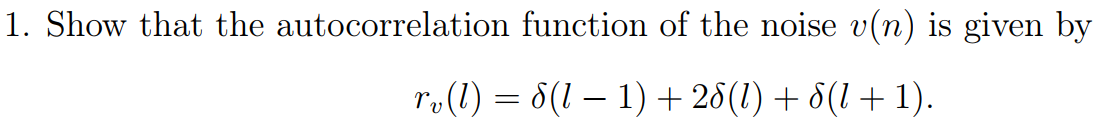

In ADSI Problem 4.9, we found that the autocorrelation for an MA(1) process where the input signal is a white noise with unit variance can be described as:

        
$$r_v \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)$$


In this problem $b_0 =b_1 =1$:

        
$$r_v \left(\ell \right)=\delta \left(\ell -1\right)+2\delta \left(\ell \right)+\delta \left(\ell +1\right)$$


r_vv = delta(-1) + 2*delta(0) + delta(1)

### 2) Compute the optimum filter coefficients

The $p$-order Wiener filter for estimating the signal $s\left(n\right)$ is given by:

        

The optimum Wiener filter coefficients is given by the Wiener-Hopf equation:

        

where ${\mathit{\mathbf{R}}}_x$ is the autocorrelation matrix of the corrupted signal $s\left(n\right)$ and $\mathit{\mathbf{g}}$ is the cross-correlation between the desired signal $s\left(n\right)$ and the corrupted signal $x\left(n\right)$.

Designing a Wiener filter to recover a corrupted signal involves 3 steps:

- Compute the autocorrelation sequence $r_x \left(\ell \right)$ and matrix $R_x$

- Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$

- Solve the Wiener-Hopf equation to find the optimum Wiener filter coefficients

**Step 1:** Compute the autocorrelation $r_x \left(\ell \right)$:

Since the signal $s\left(n\right)$ and the noise $w\left(n\right)$ are uncorrelated the autocorrelation function of $s\left(n\right)$ is just the sum of the individual autocorrelation functions:

        
$$r_x \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(s\left(n\right)+v\left(n\right)\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)v\left(n-\ell \right)+v\left(n\right)s\left(n-\ell \right)+v\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+r_{\mathrm{sv}} \left(\ell \right)+r_{\mathrm{sv}} \left(\ell \right)+r_v \left(\ell \right)$$


Since $s\left(n\right)$ and $v\left(n\right)$ are uncorrelated $r_{\mathrm{sv}} \left(\ell \right)=0$. We computed $r_v \left(\ell \right)=\delta \left(\ell -1\right)+2\delta \left(\ell \right)+\delta \left(\ell +1\right)$: 

        
$$r_x \left(\ell \right)=r_s \left(\ell \right)+r_v \left(\ell \right)$$


r_xx = r_ss + r_vv;

$$ans = 16\,w\left(n-l\right)\,w\left(n\right)+4\,w\left(n-l-1\right)\,w\left(n\right)+4\,w\left(n-l\right)\,w\left(n-1\right)+w\left(n-l-1\right)\,w\left(n-1\right)$$

R_xx = toeplitz(r_xx)

**Step 2:** Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$:

Since the desired signal is $s\left(n\right)$, the cross-correlation between $s\left(n\right)$ and $s\left(n\right)$ simplifies to the autocorrelation of the signal $r_s \left(\ell \right)$.

        
$$r_{\textrm{yx}} \left(\ell \right)=E\left\lbrack s\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                  
$$=E\left\lbrack s\left(n\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                  
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                  
$$=r_s \left(\ell \right)+r_{\mathrm{sv}} \left(\ell \right)$$


                  $=r_s \left(\ell \right)+0$   (since $s\left(n\right)$ and $v\left(n\right)$ are uncorrelated $r_{\textrm{sv}} \left(\ell \right)=0$

g = r_ss'

**Step 3:** Compute the optimum filter coefficients:

h_opt = R_xx\g

### 3) Calculate SNR before and after the Wiener filter

The signal to noise ratio of the input signal is given by

        
$${\textrm{SNR}}_i =\frac{{\left(\textrm{value}\;\textrm{of}\;\textrm{signal}\;\textrm{at}\;n=n_0 \right)}^2 }{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}=\frac{r_s \left(0\right)}{r_v \left(0\right)}$$


We know that:

        $r_s \left(\ell \right)=4\cdot 0\ldotp {25}^{|\ell |}$  and   $r_v \left(\ell \right)=\delta \left(\ell -1\right)+2\delta \left(\ell \right)+\delta \left(\ell +1\right)$

This means:

        $r_s \left(0\right)=4$  and  $r_v \left(0\right)=2$

Thus:

        
$${\textrm{SNR}}_i =\frac{r_s \left(0\right)}{r_v \left(0\right)}=\frac{4}{2}=2$$


The output SNR of the Wiener filter is given by:

        
$${\mathrm{SNR}}_o =\frac{h_{\mathrm{opt}}^T R_s h_{\mathrm{opt}} }{h_{\mathrm{opt}}^T R_v h_{\mathrm{opt}} }$$


R_ss = toeplitz(r_ss);
R_vv = toeplitz(r_vv);
SNR_o = (h_opt'*R_ss*h_opt) / (h_opt'*R_vv*h_opt)

The filter increases the SNR but only slightly. This is expected and is an excellent way to check your results.

## Exam 2018 Problem 4: Recover signal using a Wiener filter

clear variables;

### 1) Determine the autocorrelation function, $r_s \left(l\right)$

The output signal of the system is given as:

        
$$s\left(n\right)=4w\left(n\right)+w\left(n-1\right)$$


The autocorrelation of this signal is:

        
$$r_s \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(4x\left(n\right)+x\left(n-1\right)\right)\left(4x\left(n-\ell \right)+x\left(n-\ell -1\right)\right)\right\rbrack$$


                 
$$=E\left\lbrack 4x\left(n\right)4x\left(n-\ell \right)\right\rbrack +E\left\lbrack 4x\left(n\right)x\left(n-\ell -1\right)\right\rbrack +E\left\lbrack x\left(n-1\right)4x\left(n-\ell \right)\right\rbrack +E\left\lbrack x\left(n-1\right)x\left(n-\ell -1\right)\right\rbrack$$


                 
$$=16E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +4E\left\lbrack x\left(n\right)x\left(n-\ell -1\right)\right\rbrack +4E\left\lbrack x\left(n-1\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack x\left(n-1\right)x\left(n-\ell -1\right)\right\rbrack$$


syms n l w(n) 

h_opt =     0.2176
   -0.0441
    0.0176


expand((4*w(n) + w(n-1)) * (4*w(n-l) + w(n-1-l)))

                 
$$=16r_w \left(\ell \right)+4r_w \left(\ell -1\right)+4r_w \left(\ell +1\right)+r_w \left(\ell \right)$$


Since $r_w \left(\ell -1\right)=r_w \left(\ell +1\right)$

        
$$r_s \left(\ell \right)=17r_w \left(\ell \right)+8r_w \left(\ell -1\right)$$


Since the autocorrelation of unit variance white noise is $r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)=\delta \left(\ell \right)$:

        
$$r_s \left(\ell \right)=17\delta \left(\ell \right)+8\delta \left(\ell -1\right)$$


r_ss = [17, 8, 0];

mse_tap3 = 16.1735

### 2) Solve the Wiener-Hopf Equation

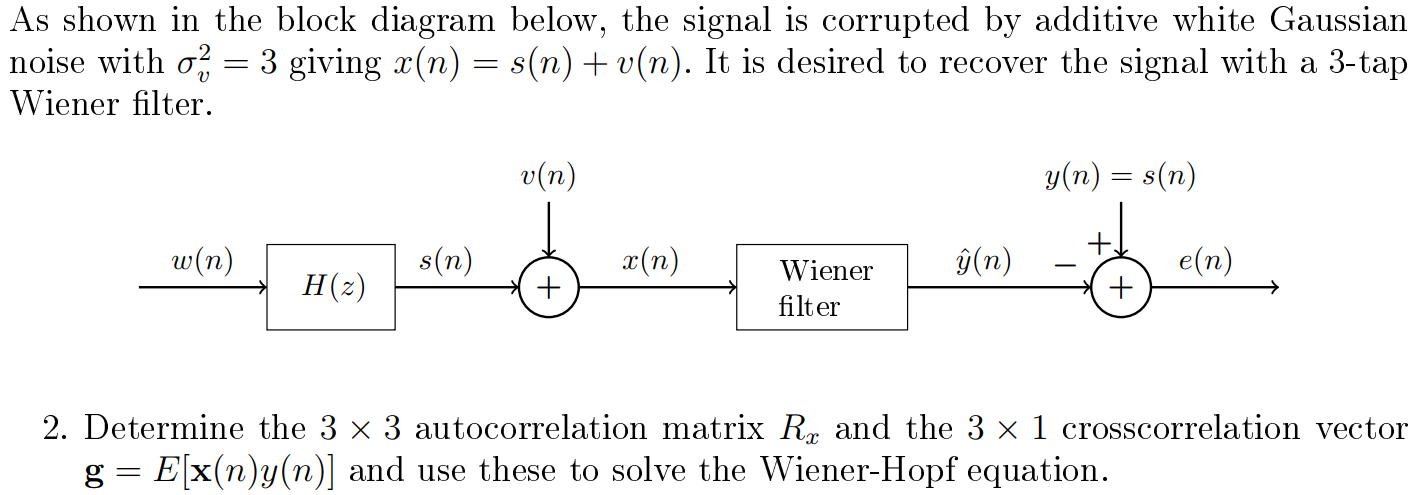

We know that $x\left(n\right)=s\left(n\right)+v\left(n\right)$ and $y\left(n\right)=s\left(n\right)=4w\left(n\right)+w\left(n-1\right)$

Assuming $w\left(n\right)$ and $v\left(n\right)$ are uncorrelated, the autocorrelation for $x\left(n\right)$:

        
$$r_x \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(s\left(n\right)+v\left(n\right)\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)v\left(n-\ell \right)+v\left(n\right)s\left(n-\ell \right)+v\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)v\left(n-\ell \right)\right\rbrack +E\left\lbrack v\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack v\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+2r_{\mathrm{sv}} \left(\ell \right)+r_v \left(\ell \right)$$


                 $=r_s \left(\ell \right)+r_v \left(\ell \right)$ (because $w\left(n\right)$ and $v\left(n\right)$ are uncorrelated so $r_{\textrm{sv}} \left(\ell \right)=0$)

                 $=17\delta \left(\ell \right)+8\delta \left(\ell -1\right)+3\delta \left(\ell \right)$  -- $r_v \left(\ell \right)=3\delta \left(\ell \right)$ since $\sigma_v^2 =3$

                 
$$=20\delta \left(\ell \right)+8\delta \left(\ell -1\right)$$


r_xx = [20, 8, 0];
R_xx = toeplitz(r_xx);

We know that $x\left(n\right)=s\left(n\right)+v\left(n\right)$ and $y\left(n\right)=s\left(n\right)=4w\left(n\right)+w\left(n-1\right)$.

Compute the cross-correlation vector:

        
$$r_{\mathrm{xy}} \left(\ell \right)=E\left\lbrack x\left(n\right)y\left(n-\ell \right)\right\rbrack$$


                  
$$=E\left\lbrack \left(s\left(n\right)+v\left(n\right)\right)\left(4w\left(n-\ell \right)+w\left(n-\ell -1\right)\right)\right\rbrack$$


                  
$$=4E\left\lbrack s\left(n\right)w\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)w\left(n-\ell -1\right)\right\rbrack +4E\left\lbrack v\left(n\right)w\left(n-\ell \right)\right\rbrack +E\left\lbrack v\left(n\right)w\left(n-\ell -1\right)\right\rbrack$$


                  
$$=4r_{\mathrm{sw}} \left(\ell \right)+r_{\mathrm{sw}} \left(\ell -1\right)+4r_{\mathrm{vw}} \left(\ell \right)+r_{\mathrm{vw}} \left(\ell -1\right)$$


We assume that  $w\left(n\right)$ and $v\left(n\right)$ are uncorrelated so $r_{\textrm{vw}} \left(\ell \right)=0$:

                  
$$=4r_{\textrm{sw}} \left(\ell \right)+r_{\textrm{sw}} \left(\ell -1\right)+0+0$$


According to Eq. 13.100, the cross-correlation $r_{\textrm{sw}} \left(\ell \right)=\sigma_w^2 h\left(\ell \right)=h\left(\ell \right)$ since $\sigma_w^2 =1$. We know that the impulse response $h\left(\ell \right)=\left\lbrack 4,1\right\rbrack$:

                  
$$=4h\left(\ell \right)+h\left(\ell -1\right)$$


g = [4, 1, 0]';

The third order Wiener filter for estimating the signal $y\left(n\right)$ is given by:

        
$$\hat{y} \left(n\right)=h_1 x\left(n\right)+h_2 x\left(n-1\right)+h_3 x\left(n-2\right)$$


The optimum Wiener filter to estimate a random process is given by Eq. 14.109:

        

where ${\mathit{\mathbf{R}}}_x$ is the correlation matrix of a random vector $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{g}}$ is the cross-correlation vector between $\mathit{\mathbf{x}}$ and $y$

h_opt = R_xx\g

mse_tap4 = 16.1723

The optimal Wiener filter is given by:

        
$$H\left(z\right)=0\ldotp 2471-{0\ldotp 1176z}^{-1} +0\ldotp 0471z^{-2}$$


### 3) Discuss whether 3 taps is an optimum choice for this problem?

We can check whether the minimum mean square error can be lowered by using a longer Wiener filter.

Typically, increasing the length of the Wiener filter lowers the MSE which means that the filter becomes better 

The minimum value of the mean square error $E\left\lbrack e^2 \left(n\right)\right\rbrack E\left\lbrack {\left(y\left(n\right)-\hat{y} \left(n\right)\right)}^2 \right\rbrack$ is given by  

        

Let us compute it for a 3-tap Wiener filter:

mse_tap3 = r_ss(1) - h_opt'*g

Let us compute it for a 4-tap Wiener filter:

R_xx4 = toeplitz([r_xx, 0]);
g4 = [g', 0]';
h_opt4 = R_xx4\g4;

mse_tap5 = 16.1720

mse_tap4 = r_ss(1) - h_opt4'*g4

Let us compute it for a 5-tap Wiener filter:

R_xx5 = toeplitz([r_xx, 0, 0]);
g5 = [g', 0, 0]';
h_opt5 = R_xx5\g5;
mse_tap5 = r_ss(1) - h_opt5'*g5

mse_tap2 = 16.1786

We observe that the minimum MSE can be lowered further by increasing the filter length. However, the decrease in minimum MSE is relatively small. If we want a faster filter, we would stick with 3-tap or even a 2-tap.

Let us compute it for a 2-tap Wiener filter:

R_xx2 = toeplitz(r_xx(1:2));
g2 = g(1:2);
h_opt2 = R_xx2\g2;
mse_tap2 = r_ss(1) - h_opt2'*g2